% Define the data for lower limit, upper limit, and frequency
lowerLimits = [45,50,55,60,65,70,75,80,85,90]; 
upperLimits = [50,55,60,65,70,75,80,85,90,95]; 
frequencies = [2,3,5,7,10,11,23,9,8,4];  

% Create a table in MATLAB
dataTable = table(lowerLimits', upperLimits', frequencies',...
    'VariableNames', {'LowerLimit', 'UpperLimit', 'Frequency'});

% Display the table
disp(dataTable);

    LowerLimit    UpperLimit    Frequency
    __________    __________    _________

        45            50            2    
        50            55            3    
        55            60            5    
        60            65            7    
        65            70           10    
        70            75           11    
        75            80           23    
        80            85            9    
        85            90            8    
        90            95            4    




% Calculate mean, median, mode, and standard deviation
data = [];
for i = 1:length(lowerLimits)
    data = [data, ones(1, frequencies(i)) * ((upperLimits(i) + lowerLimits(i)) / 2)];
end

meanValue = mean(data);
medianValue = median(data);
modeValue = mode(data);
stdDeviation = std(data);

% Calculate empirical_mode, mode_shift, and Karl
empirical_mode = 3 * medianValue - 2 * meanValue;
mode_shift = modeValue - empirical_mode;
Karl = (meanValue - modeValue) / stdDeviation;

% Display the calculated statistics
fprintf('Mean: %.2f\n', meanValue);

Mean: 73.72


fprintf('Median: %.2f\n', medianValue);

Median: 77.50


fprintf('Mode: %.2f\n', modeValue);

Mode: 77.50


fprintf('Standard Deviation: %.2f\n', stdDeviation);

Standard Deviation: 10.70


fprintf('Empirical Mode: %.2f\n', empirical_mode);

Empirical Mode: 85.06


fprintf('Mode Shift: %.2f\n', mode_shift);

Mode Shift: -7.56


fprintf('Karl: %.2f\n', Karl);

Karl: -0.35


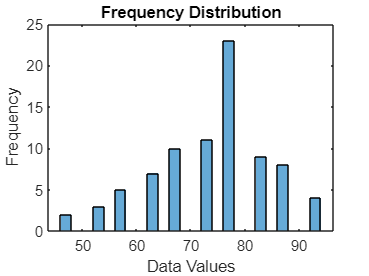


% Plotting the line graph
figure;
histogram(data, 'BinWidth', 2); % Change the 'BinWidth' according to your preference
title('Frequency Distribution');
xlabel('Data Values');
ylabel('Frequency');